# interest point Detection

img_raw = imread('picture/part1.jpg');

## write a Harris detector

computer the Ix,Iy,Iy

img = rgb2gray(img_raw);
img= imgaussfilt(img,0.1);%apple gaussian filter to the image

Ix = conv2(img, [1,0,-1], 'same'); % generate the Ix image

Iy = conv2(img, [1;0;-1], 'same'); %generate the Iy image
IxIy = Ix.*Iy; % generate Ix*Iy image
sigma = 0.3;
Ix= imgaussfilt(Ix,sigma);Iy= imgaussfilt(Iy,sigma);IxIy= imgaussfilt(IxIy,sigma); %apply gaussian filter for three new images

%computer the Harris score for each points in the picture
alpha = 0.06; %according to the original paper
[x,y]=size(img);
harris_img = zeros(x,y);
for i = 1:x
    for j = 1:y
        a = Ix(i,j)^2;
        b = IxIy(i,j);
        c = IxIy(i,j);
        d = Iy(i,j)^2;
        %harris_matrix = [(Ix(i,j))^2,Ix(i,j)*Iy(i,j);Ix(i,j)*Iy(i,j),(Iy(i,j))^2]; %create the Harris matrix
        % the formula for comupting the 
        %generate the a Harris score img for plotting
        l1 = 1/2*(a+d+(4*b*c+(a-d)^2)^0.5);
        l2 = 1/2*(a+d-(4*b*c+(a-d)^2)^0.5);
        harris_img(i,j) = l1*l2-alpha*(l1+l2)^2;
    end 
end

## Plot

R = 40;% set the threshold here
[ip_x,ip_y] = find(harris_img>R);
figure(1);imshow(img_raw);

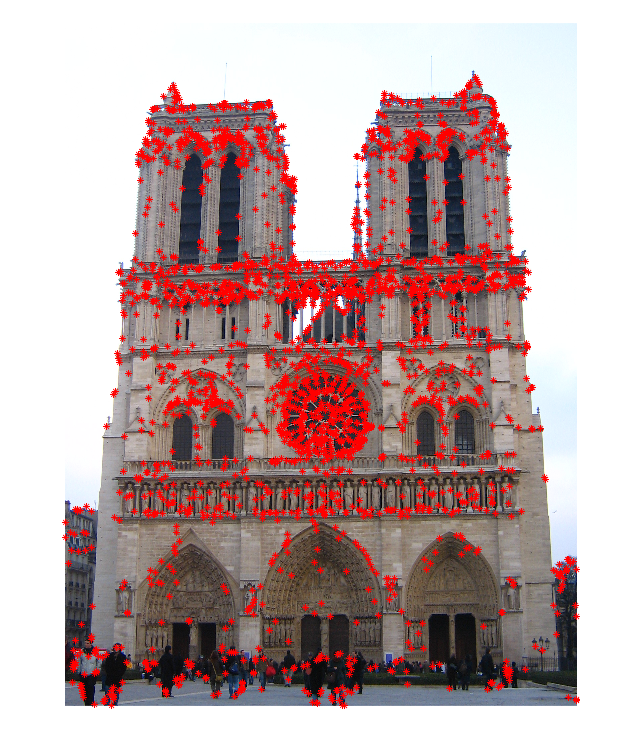

hold on; plot(ip_y,ip_x,'r*');